# 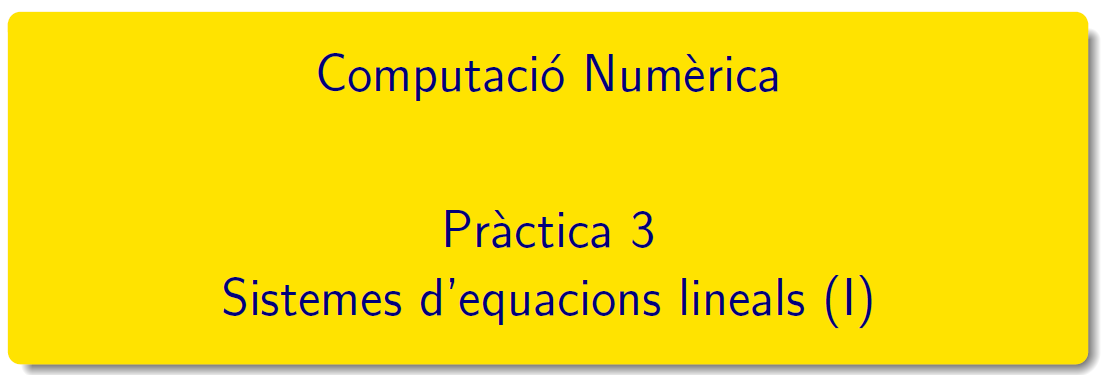

================================================================================

# Pràctica 3 - Mètodes directes

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab2-3.pdf i en el document CN_full2.pdf, els podeu trobar en el campus virtual. 

## Mètodes directes

MATLAB implementa mètodes directes a través dels operadors de divisió de matrius [`/`](https://es.mathworks.com/help/matlab/ref/mrdivide.html) i [`\`](https://es.mathworks.com/help/matlab/ref/mldivide.html), així com funcions com [`decomposition`](https://es.mathworks.com/help/matlab/ref/decomposition.html), [`lsqminnorm`](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html), and [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html).

### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

Obtindre les diferents factoritzacions de la matriu A i resoleu després el sistema lineal Ax=b


$$A=\left( \begin{array}{rrrr}
16 & 4 & 0 & -4 \\
 4 & 5 & 2 & -1 \\
 0 & 2 & 2 & -2\\
-4 & -1 & -2 & 6
\end{array} \right)$$
    
$$b=\left(\begin{array}{r}   8\\ -2\\-4\\ 3\end{array} \right)$$


format
A = [16 4 0 -4; 4 5 2 -1; 0 2 2 -2; -4 -1 -2 6]; b = [8; -2; -4;3];

Eliminació Gaussiana

AM=[A,b]

AM =     16     4     0    -4     8
     4     5     2    -1    -2
     0     2     2    -2    -4
    -4    -1    -2     6     3


% [~,U] = lugui(AM,'diagonal') x = linsolve(A)
x = U(:,1:end-1)\U(:,end)

x =    -0.5625
    1.2500
   -2.5000


Factorització LU

[L,U,P] = lu(A)

L =     1.0000         0         0         0
    0.2500    1.0000         0         0
   -0.2500         0    1.0000         0
         0    0.5000   -0.5000    1.0000


U =    16.0000    4.0000         0   -4.0000
         0    4.0000    2.0000         0
         0         0   -2.0000    5.0000
         0         0         0    0.5000


P =      1     0     0     0
     0     1     0     0
     0     0     0     1
     0     0     1     0


% comprovem PA=LU
prova = norm(P*A-L*U,1)

prova = 0

% la solució del sistema és en dos etapes, primer resolem Ly=Pb i després  Ux=y
y = linsolve(L,P*b); x = linsolve(U,y)  % linsolve més eficient

x =      1
    -1
     0
     1


z = U\(L\(P*b))

z =      1
    -1
     0
     1


Factorització de Txoleski

% verifiquem simetria iflag =0
[R,iflag] = chol(A)

R =      4     1     0    -1
     0     2     1     0
     0     0     1    -2
     0     0     0     1


iflag = 0

% comprovem R'R = A
control = norm(R'*R-A,1)

control = 0

%la solució del sistema és en dos etapes, primer resolem R'y=b i després  Rx=y
 y = linsolve(R',b); x = linsolve(R,y)  % linsolve més eficient

x =      1
    -1
     0
     1


Factorització QR

[Q,R] = qr(A), control_ortogonal=[Q*Q', Q'*Q]

Q =    -0.9428    0.2033    0.1725    0.2000
   -0.2357   -0.8642    0.1941   -0.4000
         0   -0.4575   -0.3882    0.8000
    0.2357   -0.0508    0.8842    0.4000


R =   -16.9706   -5.1854   -0.9428    5.4212
         0   -4.3716   -2.5416    0.6608
         0         0   -2.1567    5.1975
         0         0         0    0.4000


control_ortogonal =     1.0000   -0.0000   -0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000
   -0.0000    1.0000         0    0.0000    0.0000    1.0000   -0.0000    0.0000
   -0.0000         0    1.0000   -0.0000    0.0000   -0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000   -0.0000    0.0000   -0.0000    1.0000


% comprovem A=QR
norm(Q*R-A)

ans = 5.9381e-15

% La solució del sistema és Rx=Q'b
 x = linsolve(R,Q'*b)

x =     1.0000
   -1.0000
    0.0000
    1.0000


#### Exercici 1: Practiquem el·liminació gaussiana, LU, Txoleski, QR.

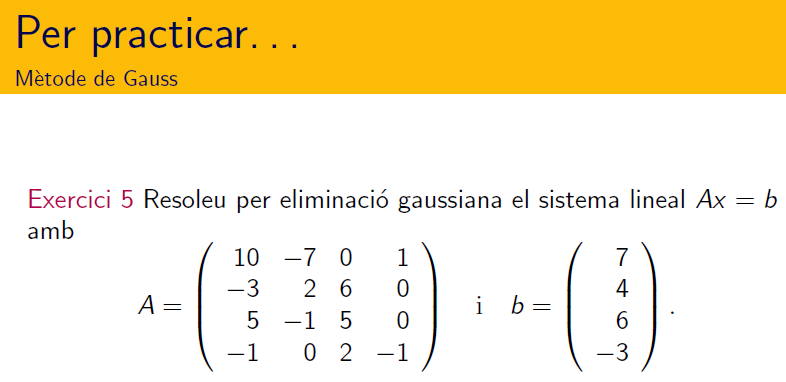

% [L,U] = lugui(AM,'diagonal');
% Si el mètode es divergent mai arribarà a la solució.
% D'altra banda, si el mètode es convergent si arribarà a solució.
clearvars
A = [ 10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1 ];
b = [ 7 4 6 -3 ]';

expected_x = linsolve(A, b)

expected_x =       0.43243
      0.21622
      0.81081
       4.1892


D = diag(diag(A));
d = diag(1 ./ diag(A));
L = tril(A, -1);
U = triu(A, -1);
n = length(A);

Bgs = -d*U;
diagGauss = inv( L + D );
Cgs = diagGauss * b;
radiGauss = max(abs(eig(Bgs)));

x = zeros(n,1);
normVal=Inf; tol=1e-8; itr=0;
while normVal>tol
    x_old=x;
    for i=1:n
        sigma=0;
        for j=1:i-1
                sigma=sigma+A(i,j)*x(j);
        end
        for j=i+1:n
                sigma=sigma+A(i,j)*x_old(j);
        end
        x(i)=(1/A(i,i))*(b(i)-sigma);
    end
    itr=itr+1;
    normVal=norm(x_old-x);
end
itrG = itr;
x_old, expected_x

x_old =   1.0789e+307
  2.5413e+307
  -5.706e+306
 -2.2201e+307


expected_x =       0.43243
      0.21622
      0.81081
       4.1892


table(itr, radiGauss, 'VariableNames',{'nº Iteracions', 'Radi Gauss'})

ans = 1×2 table
    nº Iteracions    Radi Gauss
    _____________    __________

        1147           1.4881  


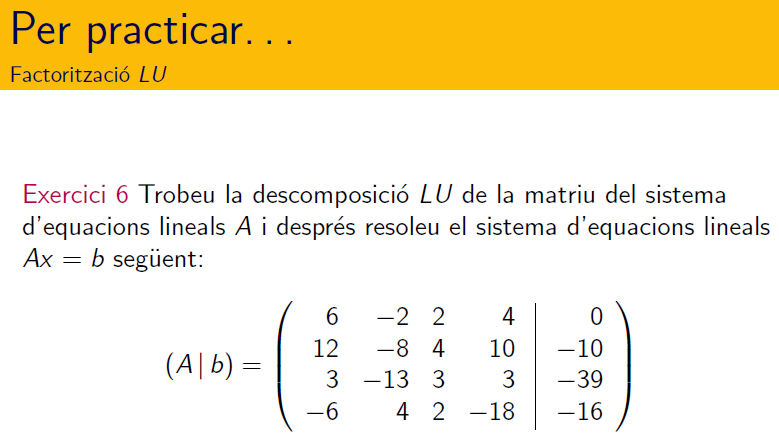

clearvars
A = [ 6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18 ];
b = [ 0 -10 -39 -16 ]';
expected_x = linsolve(A,b);
[L,U,P] = lu(A)
% comprovem PA=LU
prova = norm(P*A-L*U,1)
% la solució del sistema és en dos etapes, primer resolem Ly=Pb i després  Ux=y
y = linsolve(L,P*b); x = linsolve(U,y);  % linsolve més eficient
x, expected_x
% Càlculs per fer

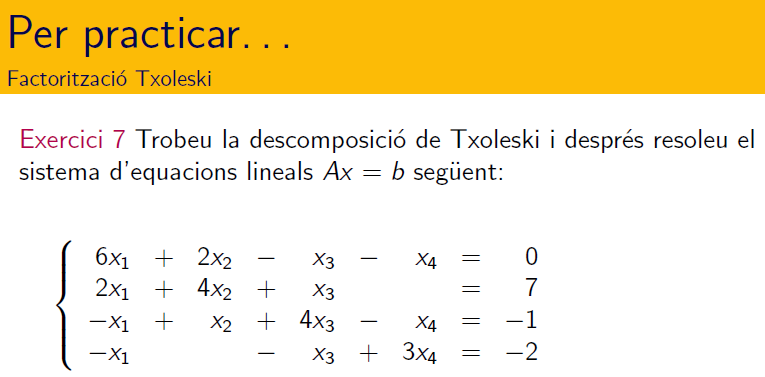

% Càlculs per fer
clearvars
A = [ 6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3 ];
b = [ 0 7 -1 -2 ]';
expected_x = linsolve(A, b);
% verifiquem simetria iflag =0

A =          0.05         0.07         0.06         0.05
         0.07          0.1         0.08         0.07
         0.06         0.08          0.1         0.09
         0.05         0.07         0.09          0.1


[R,iflag] = chol(A)

b =          0.23
         0.32
         0.33
         0.31


% comprovem R'R = A

Q =      -0.43033    -0.084395     -0.36953     -0.81923
     -0.60246     -0.57389     -0.25706      0.49154
      -0.5164      0.81019     -0.12853      0.24577
     -0.43033    -0.084395      0.88366     -0.16385


R =      -0.11619      -0.1618     -0.16439      -0.1532
            0   -0.0043885     0.022449     0.020086
            0            0     0.023939     0.040327
            0            0            0  -0.00081923


prova = ((R.')*R == A)

x =             1
            1
            1
            1


%la solució del sistema és en dos etapes, primer resolem R'y=b i després  Rx=y
y = linsolve(R.', b); x = linsolve(R, y);
x, expected_x

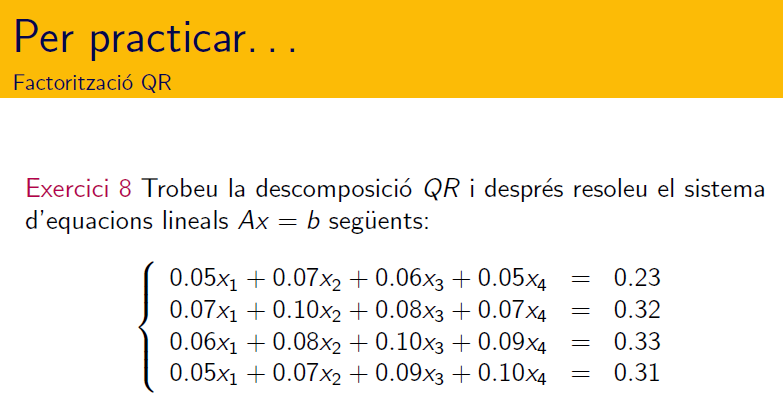

% Càlculs per fer
A=[5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100
b=[23;32; 33;31]/100

Q =      -0.43033    -0.084395     -0.36953     -0.81923
     -0.60246     -0.57389     -0.25706      0.49154
      -0.5164      0.81019     -0.12853      0.24577
     -0.43033    -0.084395      0.88366     -0.16385


R =      -0.11619      -0.1618     -0.16439      -0.1532
            0   -0.0043885     0.022449     0.020086
            0            0     0.023939     0.040327
            0            0            0  -0.00081923


[Q,R]=qr(A)
x = linsolve(R,Q'*b)

test =          0.05         0.07         0.06         0.05
         0.07          0.1         0.08         0.07
         0.06         0.08          0.1         0.09
         0.05         0.07         0.09          0.1



clearvars
A = [ 0.05 0.07 0.06 0.05; 0.07 0.10 0.08 0.07; 0.06 0.08 0.10 0.09; 0.05 0.07 0.09 0.10 ];
b = [ 0.23 0.32 0.33 0.31 ]';

x =             1
            1
            1
            1


expected_x =             1
            1
            1
            1


expected_x = linsolve(A, b);
[Q,R] = qr(A)
% comprovem A=QR
test = Q*R

% La solució del sistema és Rx=Q'b
x = linsolve(R, Q.'*b);

H =        1              1/2            1/3            1/4     
       1/2            1/3            1/4            1/5     
       1/3            1/4            1/5            1/6     
       1/4            1/5            1/6            1/7     


x, expected_x

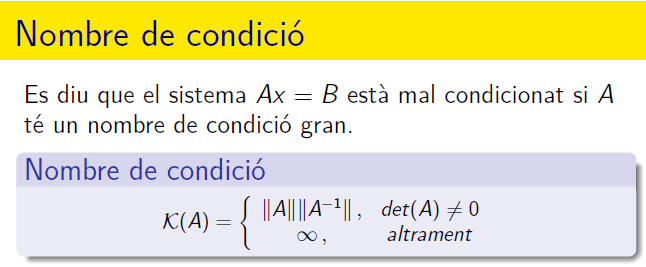

### Nombre de condició d'una matriu

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [Condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format rat

condN2 =            15513.738738929


condN1 =           28374.9999999973


condNf =           15613.7935596423


condNi =           28374.9999999973


% Returns the Hilbert matrix of order n.
H = hilb(4)
format longG
condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

**Fites error - Vector residu**

 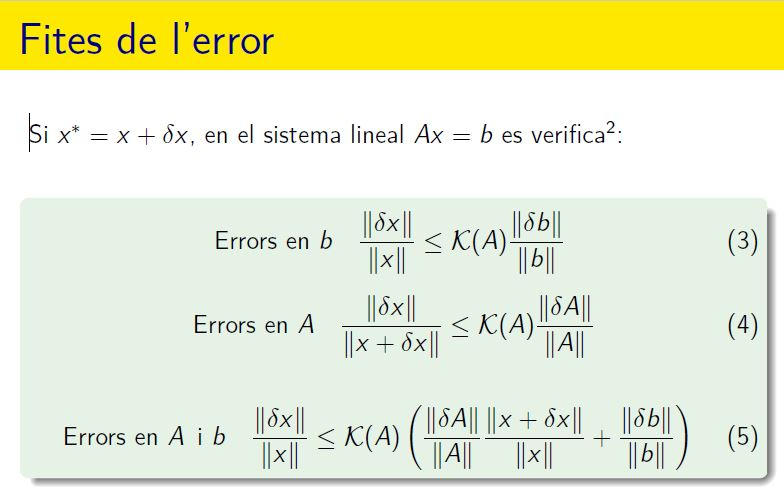     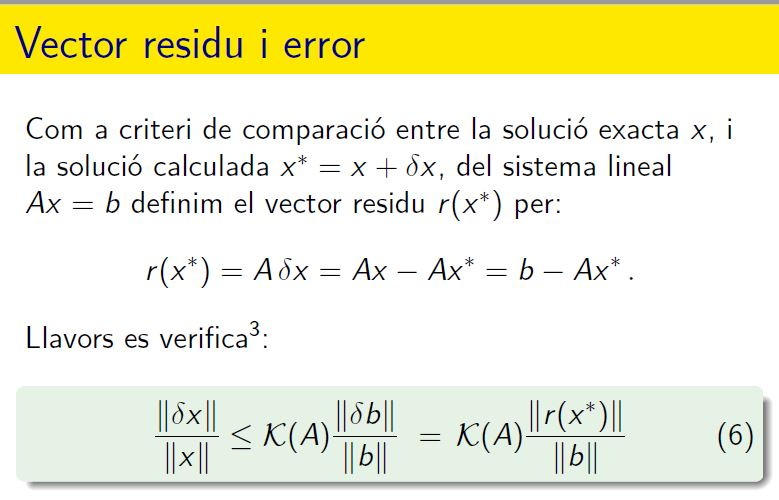

El nombre de condició d'una matriu apareix en les fites de l'error relatiu del resultat. 

Aquestes fites les podeu trobar en el llibre de la bibliografia Càlcul Numèric, Grau, M. i Noguera, M.

#### Exercici 2: Propagació dels errors en les dades d'un sistema lineal


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudiem com varia la solució del sistema lineal quan modifiquem només el terme independent $A(x+\delta x) = b+\delta b$

format shortG
A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


Sistema lineal 

b1=[32; 23; 33; 31];
b2=[32.1; 22.9; 33.1; 30.9];
B=[b1,b2], x=linsolve(A,B)

B =            32         32.1
           23         22.9
           33         33.1
           31         30.9


x =             1          9.2
            1        -12.6
            1          4.5
            1         -1.1


d = det(A)

d =             1


fprintf('paràmetres de condicionament\n'),K=cond(A,1), RK=rcond(A)

paràmetres de condicionament


K =          4488


RK =    0.00022282


fprintf('pertorbació en el vector b: db'), db = norm(b1-b2,'inf')/norm(b1,'inf')

pertorbació en el vector b: db

db =     0.0030303


fprintf('pertorbació en el vector x: dx'),dx = norm(x(:,1)-x(:,2),'inf')/norm(x(:,1),'inf')

pertorbació en el vector x: dx

dx =          13.6


fprintf('Error amplificat fp :'), fp = dx/db

Error amplificat fp :

fp =          4488



$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.1& 7.2 & 32\\
7.08 & 5.04 & 6 & 5 & 23\\
8 & 5.98 & 9.89 & 9 & 33\\
6.99 & 4.99 & 9 & 9.98& 31\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudieu com varia la solució del sistema lineal quan modifiquem només la matriu del sistema $(A+\Delta)(x+\delta x) = b$

% Càlculs per fer
A1=[10 7 8.1 7.2; 7.08 5.04 6 5; 8 5.98 9.89 9; 6.99 4.99 9 9.98]

A1 =            10            7          8.1          7.2
         7.08         5.04            6            5
            8         5.98         9.89            9
         6.99         4.99            9         9.98


fprintf('pertorbació en la matriu A: dA\n'), dA = norm(A-A1,'inf')/norm(A,'inf') 

pertorbació en la matriu A: dA


dA =     0.0090909


z = linsolve(A1,b1), x = linsolve(A,b1)

z =           -81
          137
          -34
           22


x =             1
            1
            1
            1


fprintf('pertorbació en el vector x: dx\n'), dx = norm(z-x,'inf')/norm(z,'inf')

pertorbació en el vector x: dx


dx =        0.9927


fprintf('Error amplificat fp :\n'), fp = dx/dA

Error amplificat fp :


fp =         109.2




fprintf('Error amplificat fp :\n'), fp = dx/dA

Error amplificat fp :


fp =         109.2



$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8.1& 7.2 & 32.1\\
7.08 & 5.04 & 6 & 5 & 22.9\\
8 & 5.98 & 9.89 & 9 & 33.1\\
6.99 & 4.99 & 9 & 9.98& 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


Estudiem com varia la solució del sistema lineal quan  la matriu del sistema i el vector terme independent $(A+\Delta)(x+\delta x) = b+\delta b$

% Càlculs per fer
% Càlculs per fer
w=linsolve(A1,b2), x=linsolve(A,b1)

w =        332.91
       -550.5
       143.89
      -84.585


x =             1
            1
            1
            1


fprintf('pertorbació en el vector x: dx\n'),dx = norm(w-x,'inf')/norm(x,'inf')

pertorbació en el vector x: dx


dx =         551.5


#### Exercici 3: Practiquem ...

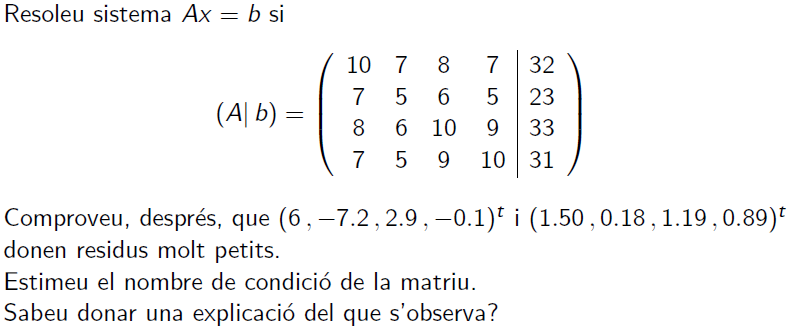

% Per fer
A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


b=[32; 23; 33; 31];
x1 = [6; -7.2; 2.9; -0.1];
x2 = [1.5; 0.18; 1.19; 0.89];
r1=norm(b-A*x1,1), dx1 =  norm(x-x1,1)

r1 =           0.4


dx1 =          16.2


r2=norm(b-A*x2,1), dx2 =  norm(x-x2,1)

r2 =          0.04


dx2 =          1.62


#### Exercici 4: Practiquem ...

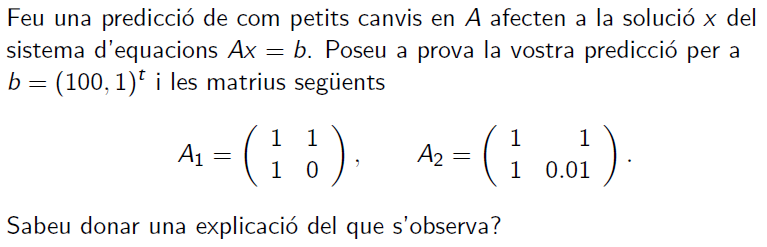

% Per fer

### Sistemes d'equacions lineals sobredeterminats

Un sistema **Ax=b**, on A és una matriu mxn (m>n) i de rang n es diu sistema sobredeterminat.  No existeix $x=(x_1,x_2,\cdots,x_n)^t$ solució. Si el conjunt de solucions de **Ax=b** és buit, amb freqüència estem interessats en trobar un vector $x_0$ que faci $||b-Ax_0||_2$ tan petit com sigui possible


$$S = \left\{ \begin{array}{rcrcrcrcr}
x & + & y & + & z &   &    & = & 2\\ 
x &   &   & + & z & + & 2t & = & 3\\ 
x & + & y &   &   & + & t  & = & 4\\
& - & y & + & 2z&   &    & = & 2\\ 
-x & + & y & - & z & + & t  & = & 1
\end{array}\right.$$
   

`Exercici 1`` Escriviu A i b i calculeu rang(A).`

A=[1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1]

A =      1     1     1     0
     1     0     1     2
     1     1     0     1
     0    -1     2     0
    -1     1    -1     1


b = [2 3 4 2 1]'

b =      2
     3
     4
     2
     1


rank(A)

ans =      4


#### Exercici 5: Equacions normals i solució per mínims quadrats. 

Trobar $x=(x_1,x_2,\cdots,x_n)^t$ tal que el vector residu ${\bf r} =\| r(x)\|_2 =  \|b-Ax\|_2 $ sigui el més petit posible, valor mínim.

- Geomètricament, ${\bf Ax} = x_1\left( \begin{array}{l}a_{11}\\\vdots\\a_{m1}\end{array}\right)+\cdots+x_n\left( \begin{array}{l}a_{1n}\\\vdots\\a_{mn}\end{array}\right)$ es tracta de trobar la combinació lineal dels vectors columna de la matriu $\bf A$més propera al vector $\bf b$. La distància és $r(x) = b-Ax
$, i el mínim es dona quan el vector $r(x)$ és perpendicular al subespai generat per els vectors columna de la matriu $\bf A$. Les equacions són ${\bf A^t\,r=A^t(b-Ax)=0}$. 

- Analíticament, si $x=(x_1,x_2,\cdots,x_n)^t$, $ {\bf r}^2\, =\displaystyle \sum_{i=1}^{m}(a_{i1}x_1+\cdots+a_{in}x_n-b_i)^2 = \displaystyle \sum_{i=1}^{m}\left( \sum_{j=1}^{n}a_{ij}x_j-b_i\right)^2$.  Els extrems locals han de verificar $\frac{\partial\, {\bf r^2}}{\partial x_j} =0$  per a tot $j=1,\dots,m$. Aquesta condició és  $2\displaystyle \sum_{i=1}^{m}\left( \sum_{k=1}^{n}a_{ik}x_k-b_i\right)^2 a_{ij} = 0$ ,  o $\displaystyle \sum_{i=1}^{m}\sum_{j=1}^{n}a_{ij}a_{ik}x_k = \sum_{i=1}^{m}a_{ij}b_i$ per a tot $j=1,\dots,m$. Escrit més compacte ${\bf A^tb=A^tAx}$.  

`Exercici 2`` Calculeu `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comprova que el sistema `${A^tAx=A^tb}$` és compatible determinat. `

AtA=A'*A, rank(AtA),det(AtA) 

AtA =      4     1     3     2
     1     4    -2     2
     3    -2     7     1
     2     2     1     6


ans =      4


ans =    175


`Exercici 3`` Calculeu `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`.  `

x1 = linsolve(AtA,A'*b)    % equacions normals

x1 =       0.14286
       1.2857
       1.2857
       1.1429


rx1 = norm(b-A*x1)

rx1 =        1.8898


`Exercici 4`` Calculeu el vector residu en la solució. Comproveu que `$y=(0,-1,2,-1)^t$`  té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

ry = norm(b-A*[0,-1,2,-1]')

ry =        8.9443


y = -1+2*rand(4,1); ryy=norm(b-A*y)

ryy =        5.8887



%ry = norm(b-A*[0,-1,2,-1]')
%y = -1+2*rand(4,1); ryy=norm(b-A*y)

Enllaç d'ajuda per [mldivide(\)](https://es.mathworks.com/help/matlab/ref/mldivide.html),  [linsolve](https://es.mathworks.com/help/matlab/ref/linsolve.html) i  [lsqminnorm](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html)

`Exercici 5``. `

`A continuació obteniu la solució del sistema S fent ús les comandes de MATLAB®: \, linsolve i lsqminnorm. Què observeu? `

vsol1 = A\b

vsol1 =       0.14286
       1.2857
       1.2857
       1.1429


sol2 = linsolve(A, b)

sol2 =       0.14286
       1.2857
       1.2857
       1.1429


sol3 = lsqminnorm(A, b)

sol3 =       0.14286
       1.2857
       1.2857
       1.1429


#### Exercici 6: Per practicar ...

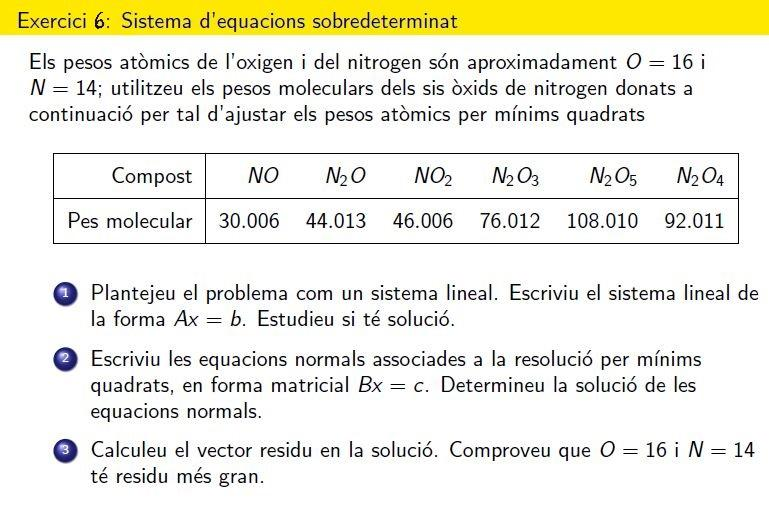

`Exercici 1`` Escriviu A i b i calculeu rang(A)`

A = [ 1 1; 2 1; 1 2; 2 3; 2 5; 2 4 ];
b = [ 30.006 44.013 46.006 76.012 108.010 92.011 ]';
rank(A)

ans =      2


`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comprova que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

At = A' * A

At =     18    29
    29    56


rank(At)

ans =      2


det(At)

ans =           167


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(A, b)

x =        14.007
       15.999


`Exercici 4``  Calculeu el vector residu en la solució. Comproveu que `$O=16$` i `$N=14$` té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

vr = b - A*x

vr =   -0.00020958
  -0.00012575
   0.00049701
   0.00028743
   -0.0002994
   -5.988e-06


`Document preparat per M. Àngela Grau Gotés, 3 de març de 2022`